# Diffusion weighted imaging

This tutorial illustrates the nature of diffusion of water in the presence of barriers, such as the cell membranes. This is the situation we find when we measure diffusion weighted images (DWI). 

The statistical issues involved in analyzing these data, and the computational methods that are available for interpreting these data, are also introduced.

- Class:       Psych 204B

- Tutorial:    Diffusion

- Author:     Dougherty

- Date:        2010.10.31

- Duration:  45 minutes

- Copyright:  Stanford University

## Self-diffusion of water

The **self-diffusion coefficient** of water describes how individual molecules move in a homogeneous substrate (pure water).  The coefficient value depends on the water temperature (T) and the atmospheric pressure (P).  

Krynicki, Green & Sawyer (1978) define the relationship (Pressure and temperature dependence of self-diffusion in water. Faraday Discuss. Chem. Soc., 66, 199 - 208.).  We use the Krynicki formula to calculate the diffusion coefficient at various temperatures. 

The  units of this formula are self-diffusion of water ($\frac{{\textrm{um}}^2 }{\textrm{ms}}$) given the temperature T (in Centigrade) and the pressure P (in kPa).

selfDiffusionOfWater = @(T,P) 12.5 .* exp(P*-5.22*10^-6) .* sqrt(T+273.15) .* exp(-925.*exp(P.*-2.6.*10^-6)./(T+273.15-(95+P.*2.61.*10^-4)));

% Standard atmospheric pressure at sea level, in kilo Pascals (kPa):
P = 101.325;

% The self-diffusion of water at body temperature and standard pressure is:
selfDiffusionOfWater(37,P)

ans = 2.9892

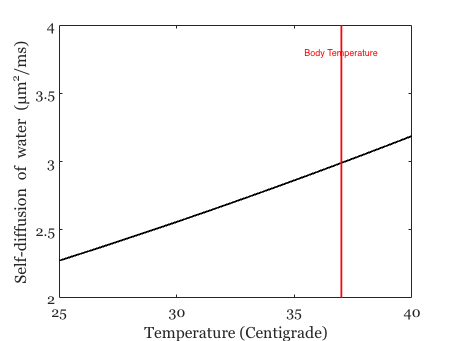


% Let's plot D for a biologically meaningful range of temperatures
T = [25:40];
D = selfDiffusionOfWater(T,P);
figure(1);
plot(T, D, 'k');
xlabel('Temperature (Centigrade)');
ylabel('Self-diffusion of water (\mum^2/ms)')

line([37 37], [2 4], 'color', 'r');
text(37, 3.8, 'Body Temperature', 'HorizontalAlignment', 'center','color','r');

(See also [http://www.lsbu.ac.uk/water/explan5.html](http://www.lsbu.ac.uk/water/explan5.html) and Mills (1973) Self-Diffusion in Normal and Heavy Water. JPhysChem 77(5), pg. 685 - 688.)

## Question 1

a. The average atmospheric pressure in Denver Colorado is about 84 kPa.  What is the difference (in percent) between the self-diffusion  coefficient of water at body temperature in Denver compared to   Palo Alto, which is about at sea level?

b. Suppose you are running a high fever of 40 C. Compared to  someone without a fever (37 C), how much higher (in percent) is the water diffusion coefficient in your body?

## Brownian motion

Here we simulatedthe Brownian motion in a small chunk of tissue. The size of the simulated voxel, in micrometers.  We include the possibility of a uniform and infinitely large substrate of water or of having a barrier, like cell membranes, surrounding the water.

First, we place the paticles randomly in a circle.

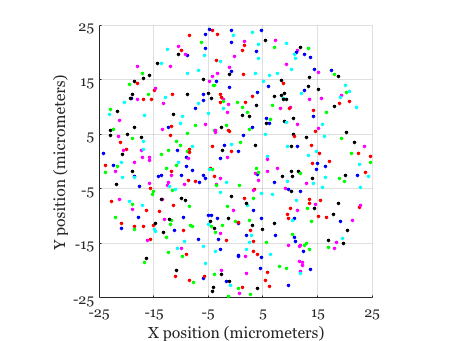

voxelSize = 50.0;   % microns
timeStep = 0.02;    % The time-step (in milliseconds):
nTimeSteps = 100;   % The number of time-steps:
ADC = 2.0;          % The ADC (in micrometers^2/millisecond)
numParticles = 500; % The number of particles to simulate:

% This parameter determines whether we set barriers to the diffusion.
% Set this to 0 for no barriers.
barrierSpacing = 0;
totalTime = 0;

% Now initialize the figure:
axLims = [-voxelSize/2 voxelSize/2];
figure(2); clf;
xlabel('X position (micrometers)');
ylabel('Y position (micrometers)');
axis square;
axis([axLims axLims]);
set(gca,'ALimMode','manual','XTick',[axLims(1):10:axLims(end)],'YTick',[axLims(1):10:axLims(end)]);

% Place particles randomly distributed in the volume
% (Note: to sample a circle uniformly, we need to take sqrt(r) to get more
% points at the larger radii.)
r = sqrt(rand(numParticles,1))*voxelSize/2;
[x,y] = pol2cart(rand(numParticles,1)*2*pi, r);
startPos = [x,y];
curPos = startPos;
hold on;

% Plot the particles
ph = zeros(numParticles,1);
for p=1:numParticles
	ph(p) = plot(curPos(p,1), curPos(p,2), '.','markerSize',12);
end

if(barrierSpacing>0)
    curCompartment = floor(curPos(:,2)/barrierSpacing);
    compartments = unique(curCompartment);
    for ii=1:numel(compartments)
        line(axLims,[compartments(ii)*barrierSpacing compartments(ii)*barrierSpacing],'color',[.2 .2 .3]);
    end
    cmap = hsv(numel(compartments));
    for p=1:numParticles
        set(ph(p), 'color', cmap(curCompartment(p)==compartments,:));
    end
end
hold off; grid on; ah = gca;

## Run the diffusion simulation

Update all the particle positions given the apparent diffusion coefficient (ADC). The diffusion equation tells us that the final position of a particle moving in Brownian motion can be described by a Gaussian distribution with a standard deviation of sqrt(ADC*timeStep). The following code  updates the particle position by drawing numbers from a Gaussian with this standard deviation.

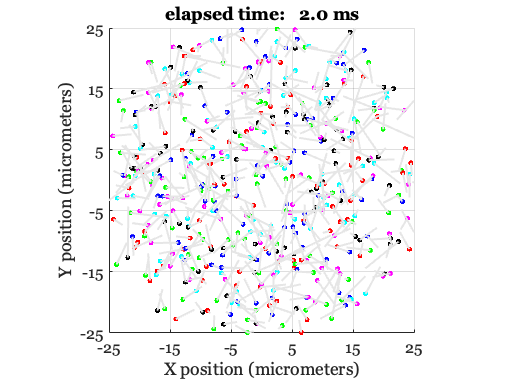

for ti=1:nTimeSteps
    d = randn(numParticles,2)*sqrt(2*ADC*timeStep);
    newPos = curPos+d;
    if(barrierSpacing>0)
        curCompartment = floor(curPos(:,2)/barrierSpacing);
        newCompartment = floor(newPos(:,2)/barrierSpacing);
        reflectTheseParticles = newCompartment~=curCompartment;
        % A simple hack to approximate particles reflecting off the impermeable barrier
        newPos(reflectTheseParticles,2) = curPos(reflectTheseParticles,2) - d(reflectTheseParticles,2);
    end
    curPos = newPos;
    % Draw the particles in their new positions:
    for p=1:numParticles
        set(ph(p), 'XData', curPos(p,1), 'YData', curPos(p,2));
    end
    
    % To avoid biasing our ADC estimates with edge effects, we allow
    % particles to move outside of our simulated voxel.
    set(get(ah,'Title'),'String',sprintf('elapsed time: %5.1f ms',timeStep*ti));
    
    % Pause is specified in seconds, so the following will play the movie
    % about 1000 times slower than reality.
    pause(timeStep-.01);
    totalTime = totalTime + timeStep;
end

% Draw a line to show where each particle came from
hold on;
sh = zeros(numParticles,1);
for p=1:numParticles
	sh(p) = plot([startPos(p,1) curPos(p,1)], [startPos(p,2) curPos(p,2)], '-', 'color', [.9 .9 .9]);
end
hold off;

## Question 2

- What is the average position change (startPos-curPos) of each particle?

- What is the average distance that each particle moved? (Hint: compute the Euclidean distance that each moved.)

## Diffusion direction

By comparing the particle ending positions (in curPos) with their starting positions (in startPos), we can compute the diffusion tensor. This is essentially just a 2-d Gaussian fit to the position differences, computied using Matlab's covariance function (cov). We also need to normalize the positions by the total time that we diffused.

Dt = cov(startPos-curPos,1)./(2*totalTime)

Dt =     1.8736    0.0942
    0.0942    2.1149



% The eigensystem of the diffusion tensor describes an isoprobability
% ellipse through the data points. 
[vec,val] = eig(Dt);
estimatedADC = diag(val)'

estimatedADC =     1.8411    2.1473


principalDiffusionDirection = vec(2,:)

principalDiffusionDirection =     0.3255    0.9455


## Question 3

- Run the simulation with and without barriers by adjusting the 'barrierSpacing' variable. How does the diffusion tensor change?

- Adjust the barrier spaceing. What effect does this have on the princpal diffusion direction? On the estimatedADC values?

- With barriers in place, reduce the number of time steps (nTimeSteps).  How does this affect the estimatedADC values? Explore the interaction between the barrier spacing and the number of time steps.